# **Flux Variability analysis (FVA)**

All COBRA predictions are derived from optimisation problems, typically formulated in the form


$$\begin{array}{lll}
\min\limits _{v \in R^{n}} & \psi( \,v ) \, \\
\text{s.t.} & Sv=b,\\
 & Cv \leq d, \\
 & l\leq v\leq u,
\end{array}$$


where $v \in R^{n}$ represents the rate of each biochemical reaction, and where a $$b_{i}<0$$, or  $$b_{i}>0$$, represents some fixed output, or input, of the ith molecular species. $$S\in\Re^{m\times n}$$ is a stoichiometric matrix for $$m$ molecular species and $$n$ reactions, and $$b$ is a vector of known metabolic exchanges. The output of FBA is a particular flux distribution, $$v$ , which maximises or minimises the objective function and stands between upper and lower bounds, $$u$ and $$l$, respectively.

The Flux variability analysis (FVA) is a computational tool that is useful for quantifying excess fluxes by identifying the set of metabolic phenotypes that result in an equivalent maximal (or minimal) objective function. This analysis is essential for identifying biochemical pathways that can potentially generate the same phenotype. It computes the minimal and maximal fluxes of each reaction for a fixed objective function [1]. 

 The FVA is used for examining changes in the distribution of metabolic fluxes under several altered conditions [1]. It solves two optimisation problems for each flux $v_{i}$ of interest:


$$\begin{array}{lll}
\max\limits _{v}/\min\limits _{v} & v_{i} \\
\text{s.t.} & Sv=b,\\
 & w^{T}v \geq  	\ddagger Z_{0} , \\
 & l\leq v\leq u,
\end{array}$$


where $$w$ is a biological objective, such as ATP production, and $Z_{0} = w^{T}v_{0}$ ia an optimal solution to LP, $\gamma$ is a parameter which controls whether the analysis is done w.r.t. suboptimal network states $$(0 \leq \gamma \leq 1)$ or to the optimal state $$(\gamma =1)$.

## EQUIPMENT SETUP

If necessary, initialize the cobra toolbox:

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

For solving linear programming problems in FBA and FVA analysis, certain solvers are required:

changeCobraSolver ('gurobi', 'all', 1);


 > Gurobi interface added to MATLAB path.
 > Solver for LPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QPproblems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQPproblems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


The present tutorial can run with `'glpk``'` package, which does not require additional installation and configuration. Although, for the analysis of large models is recommended to use the `'gurobi'` package. For detail information, refer to the solver installation guide: [https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md) 

## PROCEDURE

Before proceeding with the simulations, the path for the model needs to be set up:

pathModel = '~/work/sbgCloud/data/models/published/thiele_candidate_2005/';
filename = 'cardiac_mit_glcuptake_atpmax.mat';
load([pathModel, filename])
model = modelCardioMito;
clear modelCardioMito

In this tutorial, the provided model is a human cardiac mitochondrial model [2].

In this example, we are analysing the variability of several reactions from the human cardiac mitochondrial model in the aerobic and anaerobic state. 

First, we will close the boundaries from uptake reactions and set constraints for two different biological states:

modelfva1 = model;
exchanges = { 'EX_12dgr_m(e)'
    'EX_co2(e)'
    'EX_coa(e)'
    'EX_cys-L(e)'
    'EX_fe2(e)'
    'EX_glc(e)'
    'EX_gly(e)'
    'EX_glyc(e)'
    'EX_glyc3p(e)'
    'EX_h(e)'
    'EX_h2o(e)'
    'EX_o2(e)'
    'EX_pi(e)'
    'EX_ps_m(e)'
    'sink_cdpchol(c)'
    'sink_cmp(c)'};
for i = 1:length (exchanges)
    modelfva1 = changeRxnBounds (modelfva1, exchanges{i}, 0, 'l');
end 
 modelfva1 = changeRxnBounds (modelfva1, 'EX_glc(e)', -20, 'l');
 %modelfva2 represents aerobic condition
 modelfva2 = modelfva1;
  modelfva2 = changeRxnBounds (modelfva2, 'EX_o2(e)', -1000, 'l');

Running `fluxVariability() `on both models (`modelfva1`, `modelfva2`) will generate the minimum and maximum flux ranges of all the ractions in the network.

The code is as follows-

[minFlux1, maxFlux1, Vmin1, Vmax1] = fluxVariability(modelfva1, 0);
[minFlux2, maxFlux2, Vmin2, Vmax2] = fluxVariability(modelfva2, 0);

By fixing the `optPercentage` to zero, we specified no objective for the performed simulation.

Plotting several reactions from the results of the FVA and comparing them between the models:

index_max = find(maxFlux1 ~=0);
index_min = find(minFlux1 ~=0);
index = [index_max;index_min];
index = unique(index);
%obtain values in modelFva1
fav1_max = maxFlux1(index,1);
fav1_min = minFlux1(index,1);
%obtain values in modelFva2
fav2_max = maxFlux2(index,1);
fav2_min = minFlux2(index,1);

% find extreme values
i = find(fav1_max < 990);

%obtain new list of bounds and reactions
fav1_max = fav1_max(i,1);
fav1_min = fav1_min(i,1);
%obtain values in modelFva2
fav2_max = fav2_max(i,1);
fav2_min = fav2_min(i,1);

ymax1 = fav1_max;
ymin1 = fav1_min;
ymax2 = fav2_max;
ymin2 = fav2_min;

max =table(ymax1,ymax2)

max =     ymax1    ymax2
    _____    _____

    40       638.2
     0           0
    40        61.8
    40          40
    40          40
    20          20
    40          40
    20          20
    20          20
     0           0
     0           0
    20          20
    20          20
     0           0
     0           0
    40          80
    20          20


min =table(ymin1,ymin2)

min =     ymin1    ymin2
    _____    _____

      0        0  
    -20      -20  
      0        0  
      0        0  
      0        0  
      0        0  
      0        0  
      0        0  
      0        0  
    -40      -40  
    -40      -40  
      0        0  
      0        0  
    -40      -40  
    -40      -40  
      0        0  
      0        0  


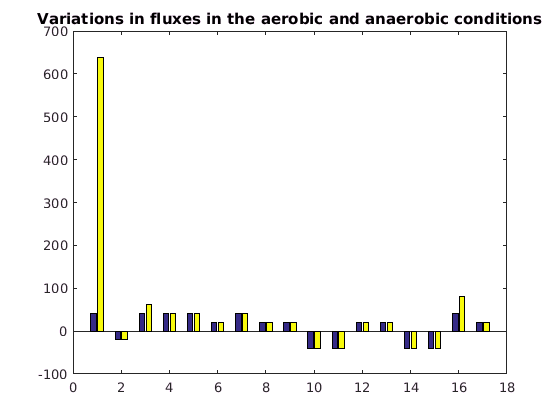


max = table2cell(max);
min = table2cell(min);

figure
plot1 = bar(cell2mat(max(1:end,:)));

hold on
plot2 = bar(cell2mat(min(1:end,:)));
title('Variations in fluxes in the aerobic and anaerobic conditions')

## REFERENCES 

[1] Gudmundsson S., and Thiele I., Computationally efficient flux variability analysis. *BMC Bioinformatics *11:489 (2010).

[2] Thiele I., et al.  Candidate Metabolic Network States in Human Mitochondria. Impact of diabetes, ischemia and diet. *J Bio Chem., 280*, 11683–11695 (2005).